# Windfarm Processing

Processing of the windfarm database consists of filtering the data, adding powercurve, and adding missing data

Add functions to the path

addpath('functions')

## Load Windturbine Data

filename = "data/WT_data/TheWindPowerDatabaseWithRotorParameters23Mar.csv";
opts = detectImportOptions(filename,'Encoding','UTF-8');
t=readtable(filename,opts);

disp("Number of Windfarm: "+ height(unique([t.Latitude t.Longitude], "row")))

Number of Windfarm: 15889


disp("Number of wind turbines: "+ sum(t.Number_of_turbines,"omitnan"))

Number of wind turbines: 116430


### Basic Filtering

Remove offshore turbine

t(~strcmp(t.Offshore_Shore_distance,'No'),:)=[];

Remove turbine not in production (i.e.,  Construction, Planned, Approved or dismantled)

t(~strcmp(t.Status,'Production'),:)=[];

Remove data without location information

t(isnan(t.Latitude) | isnan(t.Longitude),:)=[];

Remove data outside of study area as defined by the bird datase. 

To do that, we first assign to each windfarm the grid id of its location in the bird database and  then we filter for windfarm further than 50km from the closest grid id. 

load('data/2018/Density_estimationMap','g');
[dist,grid_id] = min(pdist2([g.lat2D(g.latlonmask) g.lon2D(g.latlonmask)],[t.Latitude t.Longitude],@lldistkm));
t.grid_id = grid_id';
t(dist>50,:)=[];

Display table

t

t = 12518×34 table
     ID      Continent     ISO_code      Country      State_code               Area                          City                      Name                X2nd_name         Latitude    Longitude    Altitude_Depth    Location_accuracy    Offshore_Shore_distance    Manufacturer        Turbine         Hub_height    Number_of_turbines    Total_power                     Developer                                     Operator                                        Owner                        Commissioning_date        Status        Decommissioning_date     

disp("Number of Windfarm: "+ height(unique([t.Latitude t.Longitude], "row")))

Number of Windfarm: 8429


disp("Number of wind turbines: "+ sum(t.Number_of_turbines,"omitnan"))

Number of wind turbines: 42231


## Load Power Curve data

Power curve data provide the relationship to convert windspeed into power production. This data is downloaded from ...

filename = "data/WT_data/Power_curves_20210319.xls";
opts = detectImportOptions(filename,'Sheet','Power_curves');
tp=readtable(filename,opts);

powerCurve.ws = table2array(tp(1,6:end-2));
powerCurve.ManufucturerName = tp.ManufucturerName(2:end);
powerCurve.TurbineName = tp.TurbineName(2:end);
powerCurve.Power = table2array(tp(2:end,6:end-2));

### **Smoothing Power-curve**

Because windspeed is more heterogenous (in time) than the reanalysis data, it is standard procedure to smooth the powercurve with a Gaussian of mean 0 and standard deviation proportionaly to the windspeed. Here are some equation used in the litterature

-  $\sigma =0\ldotp 2+0\ldotp 1\textrm{ws}$ (Jourdier, 2020 ; 10.5194/asr-17-63-2020): 30 min

-  $\sigma =0\ldotp 6+0\ldotp 2\textrm{ws}$ (Staffell & Pfenninger 2016 ; 10.1016/j.energy.2016.08.068) : 1hr MERRA

-  $\sigma =1\ldotp 0$ (Olauson & Bergkvist, 2015) 1hr MERRA

-  $\sigma =1\ldotp 5$ (Olauson, 2018)

As our wind databse has a 1hour resolution, we follow Staffell & Pfenninger (2016)

powerCurve.ws_smooth=powerCurve.ws(1):0.1:powerCurve.ws(end);
powerCurve.Power_smooth = nan(size(powerCurve.Power,1),numel(powerCurve.ws_smooth));

for i_p=1:size(powerCurve.Power,1)
    p = interp1(powerCurve.ws,powerCurve.Power(i_p,:),powerCurve.ws_smooth);
    % figure; plot(powerCurve.ws,powerCurve.Power(i_p,:),'or',powerCurve.ws_smooth,p,'-k')
    for i_w=1:numel(powerCurve.ws_smooth)
        s = 0.6+0.2*powerCurve.ws_smooth(i_w);
        weight = normpdf(powerCurve.ws_smooth,powerCurve.ws_smooth(i_w),s); 
        weight = weight ./sum(weight);
        powerCurve.Power_smooth(i_p,i_w)=weight*p'; 
    end
    % figure; hold on; plot(powerCurve.ws,powerCurve.Power(i_p,:)); plot(powerCurve.ws_smooth,powerCurve.Power_smooth(i_p,:)); 
end

### Add Powercurve to windturbine

We assign the power curve to each windfarm

[~,Locb] = ismember(string([t.Turbine t.Manufacturer])  , string([powerCurve.TurbineName powerCurve.ManufucturerName]),'rows');
% t2=t(Locb==0,:);
t.powerCurve = nan(size(t,1),numel(powerCurve.ws_smooth));
t.powerCurve(Locb~=0,:) = powerCurve.Power_smooth(Locb(Locb~=0),:);

It would be nicer to do use the join function, but thes function requires that all windfarms have a matching powercurve. Hence, we use ismemeber()

%t2=join(t,tp,'LeftKeys','ID','RightKeys','Turb_ID');

### Analysis of cut-in and cut-off

Compute the cut-in and cut-off value for each powercurve

Cutin = powerCurve.ws(sum(cumprod(powerCurve.Power==0,2),2));
Cutoff = powerCurve.ws(length(powerCurve.ws)-sum(cumprod(fliplr(powerCurve.Power)==0,2),2));

To plot the histogram of cut-in and cut-off, we need to accounts for each windfarm size (number of windturbines).

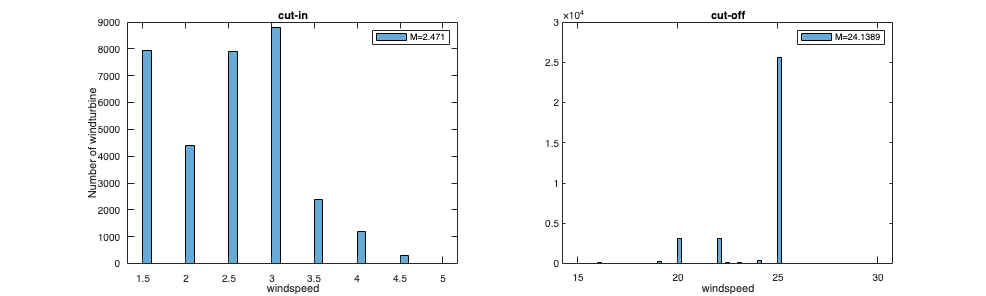

Cutin_h = repelem(Cutin(Locb(Locb~=0)),t.Number_of_turbines(Locb~=0));
Cutoff_h = repelem(Cutoff(Locb(Locb~=0)),t.Number_of_turbines(Locb~=0));
figure('position',[0 0 1000 300]); 
subplot(1,2,1)
histogram(Cutin_h); xlabel('windspeed'); ylabel('Number of windturbine'); title('cut-in');  legend(['M=' num2str(mean(Cutin_h))])
subplot(1,2,2)
histogram(Cutoff_h); xlabel('windspeed'); title('cut-off'); legend(['M=' num2str(mean(Cutoff_h))])

%Cutin(Locb(Locb~=0)).*t.Number_of_turbines(Locb~=0).*t.turbine_sweptArea(Locb~=0))

## Data Imputation

Several method exist for missing data: median, GLM or kNN (or more sofisticated like MICE). 

Illustration of available data

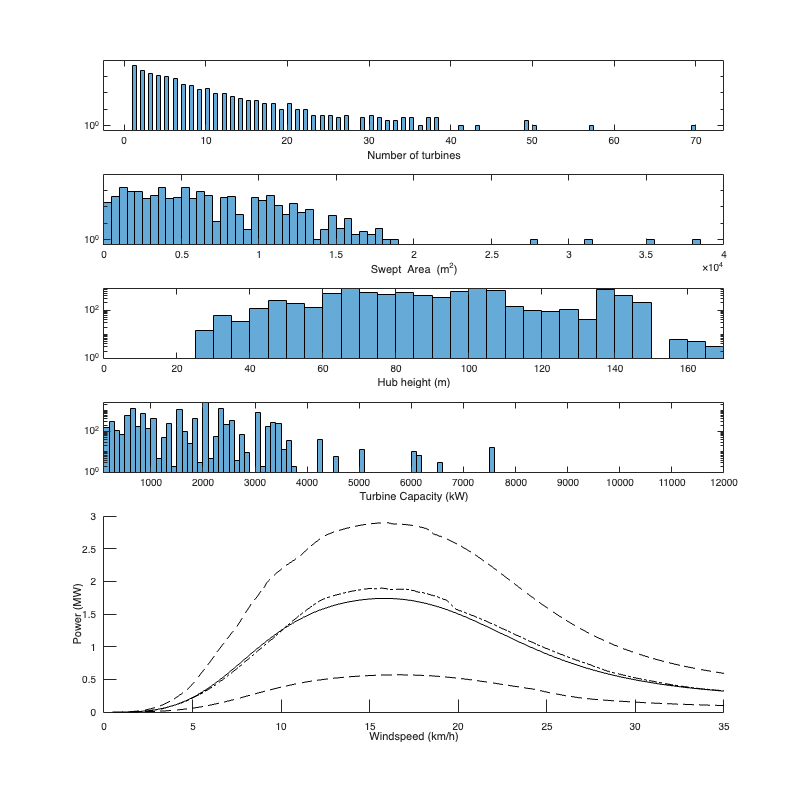

var_test = {'turbine_sweptArea','turbine_capacity','Hub_height','Number_of_turbines','Total_power','powerCurve'};
figure('position',[0 0 1000 1000]); 
subplot(6,1,1); histogram(t.Number_of_turbines); xlabel('Number of turbines'); ylim([0.5 10000]);set(gca, 'YScale', 'log')
subplot(6,1,2); histogram(t.turbine_sweptArea); xlabel('Swept Area (m^2)'); ylim([0.5 10000]); xlim([0 40000]); set(gca, 'YScale', 'log')
subplot(6,1,3); histogram(t.Hub_height); xlabel('Hub height (m)'); axis tight;set(gca, 'YScale', 'log'); xlim([0 170]);
subplot(6,1,4); histogram(t.turbine_capacity); xlabel('Turbine Capacity (kW)'); axis tight;set(gca, 'YScale', 'log')
subplot(6,1,[5 6]); hold on;
plot(powerCurve.ws_smooth, nanmean(t.powerCurve/1000),'k');
plot(powerCurve.ws_smooth, nanmedian(t.powerCurve/1000),'-.k');
plot(powerCurve.ws_smooth, quantile(t.powerCurve/1000,0.1),'--k');
plot(powerCurve.ws_smooth, quantile(t.powerCurve/1000,.9),'--k'); 
ax=gca; ylabel('Power (MW)'); xlabel('Windspeed (km/h)')

var_test = {'turbine_sweptArea','turbine_capacity','Hub_height','Number_of_turbines','Total_power','powerCurve'};
a=sprintf([num2str(nansum(t.Number_of_turbines)) '\t windfarms\n']);
for i=1:numel(var_test)
    tmp = nansum(t.Number_of_turbines(all(isnan(t.(var_test{i})),2)));
    a=[a sprintf([num2str(tmp) '(' num2str(100*tmp/nansum(t.Number_of_turbines)) 'perc)\t windfarms without ' var_test{i} '\n' ])];
end
disp(a)

42231	 windfarms
65(0.15392perc)	 windfarms without turbine_sweptArea
65(0.15392perc)	 windfarms without turbine_capacity
13532(32.0428perc)	 windfarms without Hub_height
0(0perc)	 windfarms without Number_of_turbines
65(0.15392perc)	 windfarms without Total_power
9325(22.0809perc)	 windfarms without powerCurve



Old Illustration

% var_test = {'turbine_sweptArea','turbine_capacity','Hub_height','Number_of_turbines','Total_power'};
% figure('position',[0 0 1000 1000]); 
% for i1=1:numel(var_test)
%     for i2=(i1+1):numel(var_test)
%         subplot(numel(var_test),numel(var_test),i2+(i1-1)*numel(var_test)); hold on
%         plot(t.(var_test{i2}),t.(var_test{i1}),'.k'); 
%         if i2==i1+1, xlabel(strrep(var_test{i2},'_',' ')); ylabel(strrep(var_test{i1},'_',' ')); end
%         l=lsline; l.Color='r'; 
%         box on;
%     end
% end

Create new variable for imputated value

tim=t;

### Windfarm level: `Number_of_turbines `Turbine_capacity` and` `Total_power`

First, we deal with value at the windfarm level. Three variables are linked, with total power = number_of_turbine x turbine_capacity. 

Check occurane of `nan` with either/or these two variable.

X=[tim.Number_of_turbines tim.Total_power tim.turbine_capacity];
[a1,~,c] = unique(isnan(X),'rows');
table(~a1(:,1), ~a1(:,2), ~a1(:,3) ,histcounts(c)','variableNames',{'Number of turbine','Total power','Turbine capacity','Number'})

ans = 1×4 table
    Number of turbine    Total power    Turbine capacity    Number
    _________________    ___________    ________________    ______

          true              true             true           12518 


For all the missing windfarm, we missing two variables, so we can't fill them up easily. 

We first fill-up `Number_of_turbines` and `Total_power` at the same time.We perform the prediction for both variable with a fglm 

mdl = fitglm(tim.Number_of_turbines, tim.Total_power)

mdl = Generalized linear regression model:
    y ~ 1 + x1
    Distribution = Normal

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     364.57     53.021     6.876    6.4498e-12
    x1              1698.6     10.641    159.63             0


12518 observations, 12516 error degrees of freedom
Estimated Dispersion: 1.87e+07
F-statistic vs. constant model: 2.55e+04, p-value = 0

[ypred,yci] = predict(mdl,tim.Number_of_turbines(isnan(tim.Total_power),:));
tim.Total_power(isnan(tim.Total_power)) = ypred;

mdl2 = fitglm(tim.Total_power,tim.Number_of_turbines)

mdl2 = Generalized linear regression model:
    y ~ 1 + x1
    Distribution = Normal

Estimated Coefficients:
                   Estimate         SE        tStat     pValue
                   _________    __________    ______    ______

    (Intercept)      0.97952      0.024067      40.7      0   
    x1             0.0003948    2.4732e-06    159.63      0   


12518 observations, 12516 error degrees of freedom
Estimated Dispersion: 4.35
F-statistic vs. constant model: 2.55e+04, p-value = 0

[ypred,yci] = predict(mdl2,tim.Total_power(isnan(tim.Number_of_turbines),:));
tim.Number_of_turbines(isnan(tim.Number_of_turbines)) = round(ypred);

Ilustration

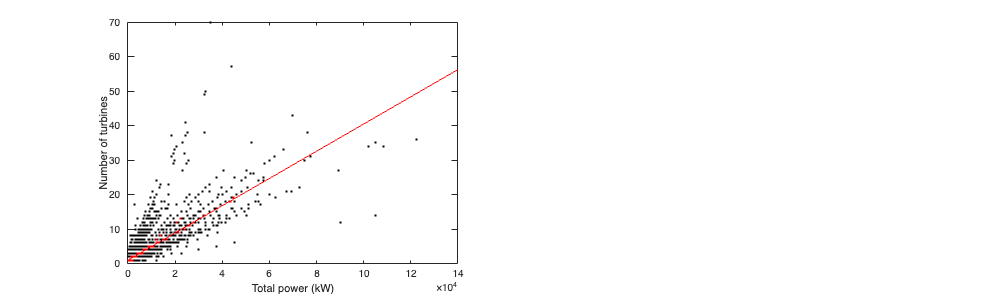

figure('position',[0 0 1000 300]);
subplot(1,2,1); hold on; box on;
plot(t.Total_power,t.Number_of_turbines,'.k'); l=lsline; l.Color='r'; 
plot(tim.Total_power(isnan(t.Total_power)|isnan(t.Number_of_turbines)),tim.Number_of_turbines(isnan(t.Total_power)|isnan(t.Number_of_turbines)),'.r'); 
xlabel('Total power (kW)'); ylabel('Number of turbines');

Then, we fill-up turbine capacity

Wind turbine capacity is directly related to total power and number of windturbine

tim.turbine_capacity(isnan(tim.turbine_capacity)) = tim.Total_power(isnan(tim.turbine_capacity)) ./ tim.Number_of_turbines(isnan(tim.turbine_capacity));

Illustration

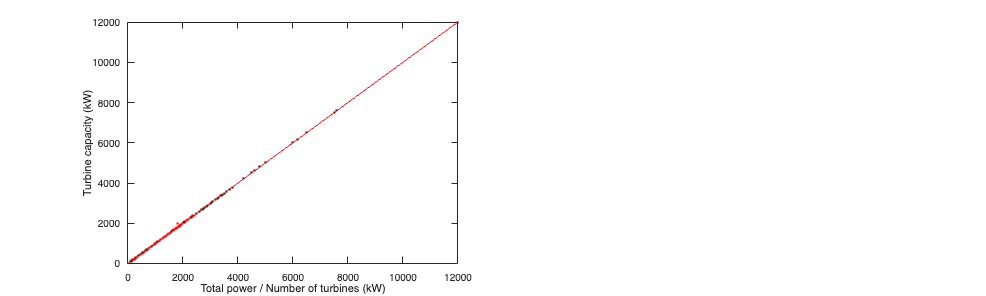

figure('position',[0 0 1000 300]);
subplot(1,2,1); hold on
plot(t.Total_power ./ t.Number_of_turbines , t.turbine_capacity , '.k' ); l=lsline; l.Color='r'; 
plot(tim.Total_power(isnan(t.turbine_capacity)) ./ tim.Number_of_turbines(isnan(t.turbine_capacity)) , tim.turbine_capacity(isnan(t.turbine_capacity)) , '.r' );
xlabel('Total power / Number of turbines (kW)'); ylabel('Turbine capacity (kW)'); box on;

### Windturbine level: `Hub_height` and turbine_sweptArea

At the windturbine level, we are missing a lot of hub height. Hub height is well related to turbine capacity and swept area.

Check occurane of nan for the three variable

X=[tim.turbine_sweptArea tim.turbine_capacity tim.Hub_height];
[a1,~,c] = unique(isnan(X),'rows');
table(~a1(:,1), ~a1(:,2), ~a1(:,3) ,histcounts(c)','variableNames',{'Swept area','Turbine capacity','hub height','Number'})

ans = 4×4 table
    Swept area    Turbine capacity    hub height    Number
    __________    ________________    __________    ______

      true             true             true         8167 
      true             true             false        4185 
      false            true             false         165 
      false            false            false           1 


Hub height can be determined from swept area and/or turbine capacity for 4K cases.

First, we build a glm with `turbine_capacity` and `turbine_sweptArea` and predict only for nan value in `Hub_height`: 

mdl = fitglm([tim.turbine_sweptArea tim.turbine_capacity],tim.Hub_height)

mdl = Generalized linear regression model:
    y ~ 1 + x1 + x2
    Distribution = Normal

Estimated Coefficients:
                   Estimate         SE        tStat       pValue   
                   _________    __________    ______    ___________

    (Intercept)       49.763       0.46652    106.67              0
    x1             0.0052245    0.00013783    37.905    9.2783e-290
    x2             0.0073252    0.00048016    15.256      7.805e-52


8167 observations, 8164 error degrees of freedom
Estimated Dispersion: 330
F-statistic vs. constant model: 6.34e+03, p-value = 0

[ypred,yci] = predict(mdl,[tim.turbine_sweptArea(isnan(tim.Hub_height),:) tim.turbine_capacity(isnan(tim.Hub_height),:)]);
ypred(ypred>max(tim.Hub_height))=max(tim.Hub_height); % Avoid missleading value of hubheight
tim.Hub_height(isnan(tim.Hub_height)) = ypred;

Then, we build a glm with `turbine_capacity` and predict only for nan value in `Hub_height`: 

mdl = fitglm(tim.turbine_capacity,tim.Hub_height)

mdl = Generalized linear regression model:
    y ~ 1 + x1
    Distribution = Normal

Estimated Coefficients:
                   Estimate        SE        tStat     pValue
                   ________    __________    ______    ______

    (Intercept)      47.962       0.30583    156.83      0   
    x1             0.023158    0.00015658     147.9      0   


12352 observations, 12350 error degrees of freedom
Estimated Dispersion: 270
F-statistic vs. constant model: 2.19e+04, p-value = 0

[ypred,yci] = predict(mdl,tim.turbine_capacity(isnan(tim.Hub_height),:));
% ypred(ypred>max(tim.Hub_height))=max(tim.Hub_height); % Avoid missleading value of hubheight
tim.Hub_height(isnan(tim.Hub_height)) = ypred;

Finally, we build a glm with `turbine_capacity` and predict only for nan value in `turbine_sweptArea`: 

mdl = fitglm(tim.turbine_capacity,tim.turbine_sweptArea);
[ypred,yci] = predict(mdl,tim.turbine_capacity(isnan(tim.turbine_sweptArea),:));
% ypred(ypred>max(tim.Hub_height))=max(tim.Hub_height); % Avoid missleading value of hubheight
tim.turbine_sweptArea(isnan(tim.turbine_sweptArea)) = ypred;

Ilustration

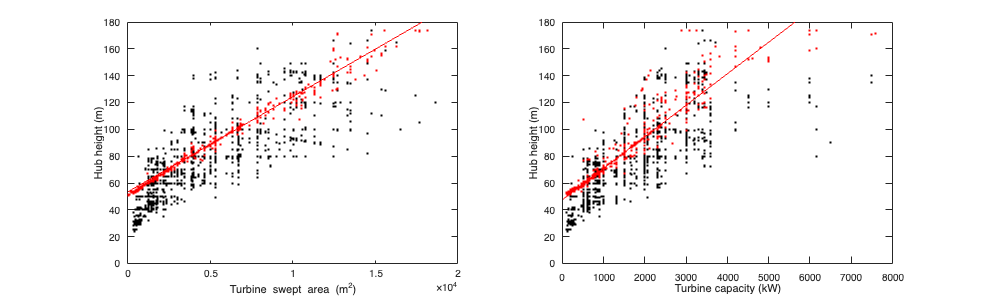

figure('position',[0 0 1000 300]);
subplot(1,2,1); hold on
plot(t.turbine_sweptArea,t.Hub_height,'.k'); l=lsline; l.Color='r'; 
plot(tim.turbine_sweptArea(isnan(t.Hub_height)),tim.Hub_height(isnan(t.Hub_height)),'.r'); 
xlabel('Turbine swept area (m^2)'); ylabel('Hub height (m)');  ylim([0 180]); xlim([0 20000])
box on;
subplot(1,2,2); hold on
plot(t.turbine_capacity,t.Hub_height,'.k'); l=lsline; l.Color='r'; 
plot(tim.turbine_capacity(isnan(t.Hub_height)),tim.Hub_height(isnan(t.Hub_height)),'.r'); ylim([0 180]); xlim([0 8000])
xlabel('Turbine capacity (kW)'); ylabel('Hub height (m)');
box on;

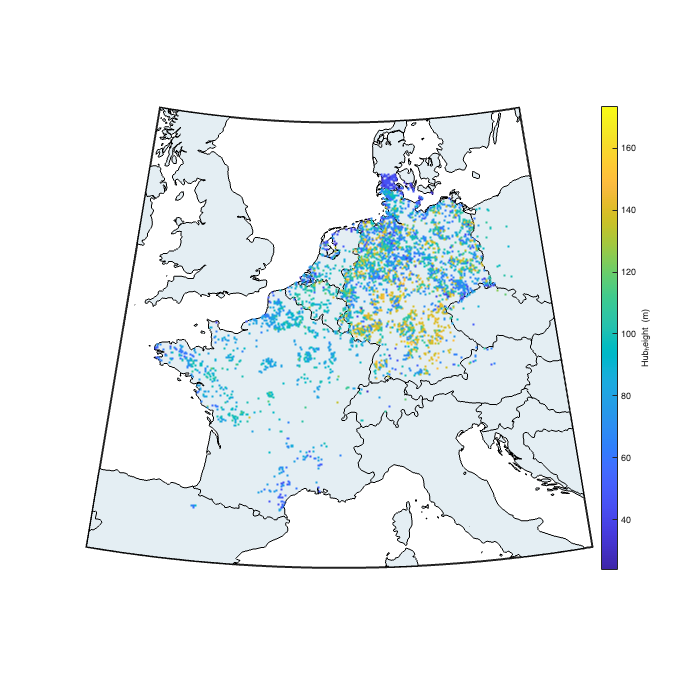

figure('position',[0 0 700 700]); hold on;
h = worldmap([min(tim.Latitude)-2 max(tim.Latitude)+2], [min(tim.Longitude)-2 max(tim.Longitude)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255);
% surfm(g.lat,g.lon,turbineSweptAreaMap)
scatterm(t.Latitude, t.Longitude, [], t.Hub_height,'.');
c=colorbar; c.Label.String='Hub_height (m)';

We can then assess the missing value in the new imputated table

var_test = {'turbine_sweptArea','turbine_capacity','Hub_height','Number_of_turbines','Total_power'};
a=sprintf([num2str(size(tim,1)) '\t windfarms\n' ]);
for i=1:numel(var_test)
    a=[a sprintf([num2str(sum(all(isnan(tim.(var_test{i})),2))) '\t windfarms without ' var_test{i} '\n' ])];
end
disp(a)

12518	 windfarms
1	 windfarms without turbine_sweptArea
1	 windfarms without turbine_capacity
1	 windfarms without Hub_height
1	 windfarms without Number_of_turbines
1	 windfarms without Total_power



The remaining missing data (if any) can be filled with the median value. 

for i=1:numel(var_test)
    tim.(var_test{i})(isnan(tim.(var_test{i})))=nanmedian(tim.(var_test{i}));
end

### Power Curve

To input the power curve, we parametrize the power curve function based on its max value which corresponds to the windturbine capacity.

We first build a power curve template based on the median value of all windfarm (note that we use tim here)

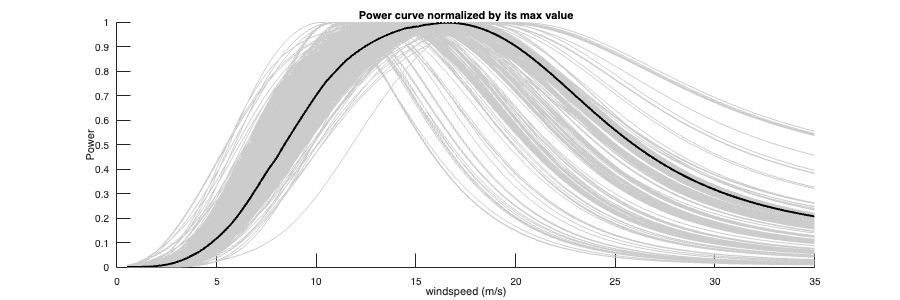

powerCurve_template = nanmedian(tim.powerCurve'./max(tim.powerCurve,[],2)',2);
figure('position',[0 0 900 300]); hold on
plot(powerCurve.ws_smooth,(powerCurve.Power_smooth'./max(powerCurve.Power_smooth,[],2)'),'color',[.8 .8 .8])
plot(powerCurve.ws_smooth, powerCurve_template,'k','linewidth',2)
xlabel('windspeed (m/s)'); ylabel('Power'); title('Power curve normalized by its max value')

The maximum value of the powercurve is well related to the turbine capacity

Use GLM to impute max powercurve based on turbine capacity

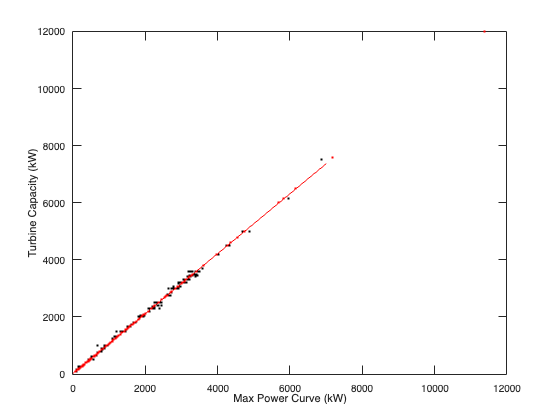

mdl = fitglm(tim.turbine_capacity,max(tim.powerCurve,[],2) );
[ypred,yci] = predict(mdl,tim.turbine_capacity(isnan(max(tim.powerCurve,[],2)),:));
% ypred(ypred>max(tim.powerCurve(:)))=max(tim.powerCurve(:));
tim.powerCurve(isnan(max(tim.powerCurve,[],2)),:) = powerCurve_template' .* ypred;
figure; hold on; box on;
plot(max(t.powerCurve,[],2),t.turbine_capacity,'.k');l=lsline; l.Color='r'; 
plot(max(tim.powerCurve(isnan(max(t.powerCurve,[],2)),:),[],2),t.turbine_capacity(isnan(max(t.powerCurve,[],2))),'.r');
xlabel('Max Power Curve (kW)'); ylabel('Turbine Capacity (kW)')

## Windfarm database characteristics

disp(['Number of Windfarms: ' num2str(height(tim))])

Number of Windfarms: 12518


disp(['Number of Windturbines: ' num2str(nansum(tim.Number_of_turbines))])

Number of Windturbines: 42696


disp(['Total power: ' num2str(nansum(tim.Total_power*1000/1e9))])

Total power: 77.0891


Group by country

tim.Total_sweptArea = tim.turbine_sweptArea.*tim.Number_of_turbines;
groupsummary(tim,'Country','sum',{'Number_of_turbines' 'Total_power','Total_sweptArea'})

ans = 11×5 table
         Country          GroupCount    sum_Number_of_turbines    sum_Total_power    sum_Total_sweptArea
    __________________    __________    ______________________    _______________    ___________________

    {'Austria'       }         13                  31                    47920           1.4496e+05     
    {'Belgium'       }        260                 811               1.8390e+06           5.2464e+06     
    {'Czech Republic'}         45                 124               2.2289e+05           6.5768e+05     
    {'Denmark'       }        310                 495               3.8384e+05           9.3967e+05     
    {'France'        }       1421                7614               1.6036e+07           4.7636e+07     
    {'Germany'       }       9703               30472               5.3427e+0

*GroupCount=number of windfarm

Distance to cast

load('coastlines.mat')
tmp = pdist2([tim.Latitude tim.Longitude],[coastlat coastlon], @lldistkm);
tim.distCoast = min(tmp,[],2);

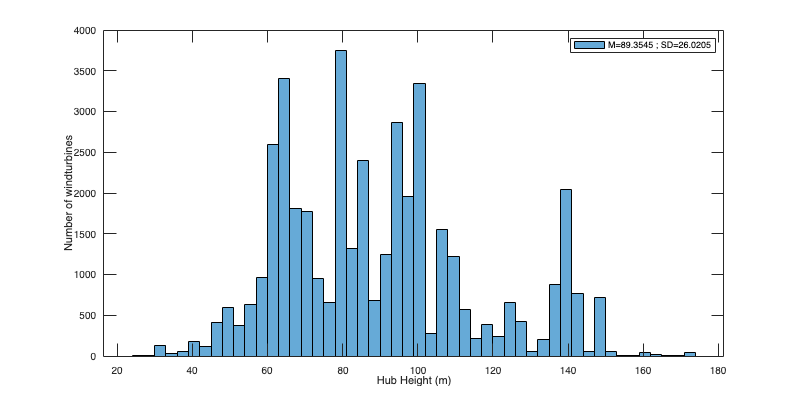

hh = repelem(tim.Hub_height,tim.Number_of_turbines);
figure('position',[0 0 800 400]); 
histogram(hh); ylabel('Number of windturbines'); xlabel('Hub Height (m)');
legend(['M=' num2str(mean(hh)) ' ; SD=' num2str(std(hh)) ])

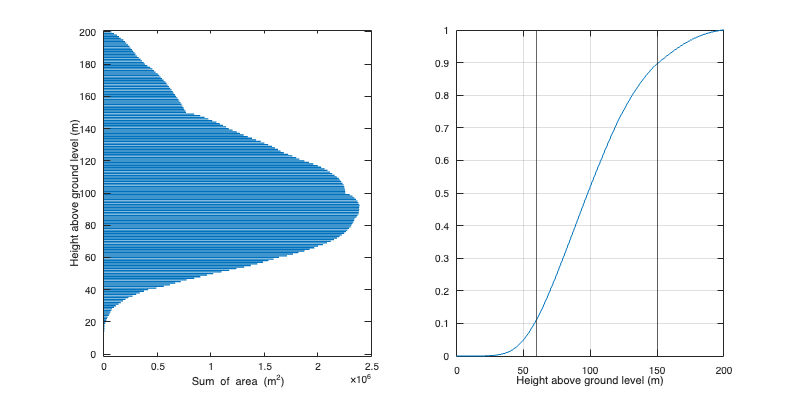

rr = repelem(tim.turbine_rotorRadius,tim.Number_of_turbines);
hhhh = repelem(tim.Hub_height,tim.Number_of_turbines);
h=0:200;
tmp = real(2*sqrt(rr.^2 - (h-hhhh).^2));
tmp = tmp ./ sum(tmp,2) .* rr.^2*pi;
figure('position',[0 0 800 400]); 
subplot(1,2,1); barh(h,nansum(tmp))
ylabel('Height above ground level (m)'); xlabel('Sum of area (m^2)');
subplot(1,2,2); plot(h,cumsum(nansum(tmp))./sum(tmp(:),'omitnan'))
xlabel('Height above ground level (m)'); grid on; axis tight; xline([60 150])

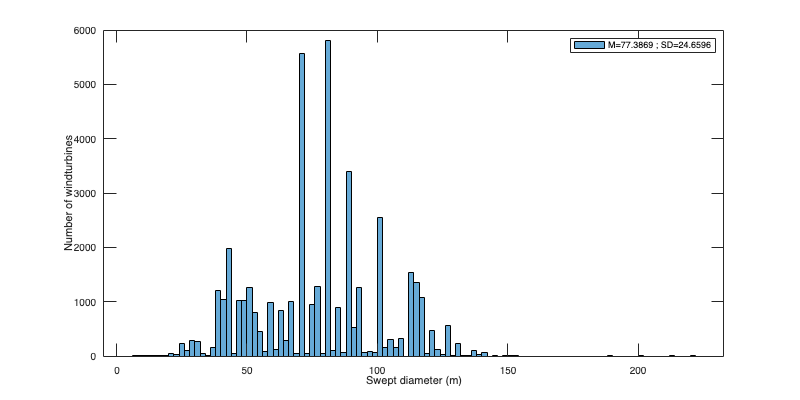

dd = repelem(sqrt(tim.turbine_sweptArea/pi)*2,tim.Number_of_turbines);
figure('position',[0 0 800 400]); 
histogram(dd); ylabel('Number of windturbines'); xlabel('Swept diameter (m)');
legend(['M=' num2str(mean(dd)) ' ; SD=' num2str(std(dd)) ])

## Save

save('data/windfarms_processed.mat', 'tim')